# Manipulability

Manipulability is a key concept in robotics that quantifies how easily a manipulator can produce motion or exert forces in different directions from a given configuration. It is closely linked to the properties of the robot's Jacobian matrix, which maps joint velocities to end-effector velocities. By studying the  *rank* of the Jacobian, we can determine whether the robot can achieve arbitrary velocities in task space or if it is operating under constraints. Situations where the Jacobian loses rank are known as *singularities. At these singularity *configurations certain directions of motion become unattainable or require disproportionately large joint velocities. Conversely, robots with more joints than the minimum required to perform a task exhibit *redundancy*, which can be exploited to improve manipulability, avoid obstacles, or optimize secondary criteria. Understanding these interrelated concepts is essential for effective motion planning, control, and safe operation of robotic manipulators.

**1. Manipulability Ellipsoids**

By computing the manipulability of the endeffector, we can visualize it as an ellipsoid. 

By projecting the Jacobian into the task space, we can visualize the set of achievable end-effector velocities for a unit norm of joint velocities. The eigenvalues and eigenvectors of $J_p$ or $J_{\Theta \;}$define the elipsoid shape, where the eigenvectors correspond to the direction and the eigenvalue to the length of this axis. This set forms an **ellipsoid**:

- **Large axes** → motion is easy in that direction.

- **Small axes** → motion is limited.

- **Collapsed axes** → motion is impossible in that direction (singularity).

Consider the UR3e robot in a random configuration

ur3e = loadrobot("universalUR3e", "DataFormat","column");


%config = [0,-pi/2,0,-pi/2,0,0]'; 
config = randomConfiguration(ur3e); 
config = [0,-pi/1.5, pi/2.5, -pi/2,-pi/2,0]'; 
% config = [0,-pi/2,0,-pi/2,0,0]'; 




for the each part of the Jacobian (translation and rotation) we can compute the axis using the singular value decomposition (SVD). With 


$$J_t \;=U*\Sigma *V\prime$$


where U is a matrix of the semi axis vectors of the elipsoid, $\Sigma$ holds the singular values, $\sigma_i$, which are equal to the length of the axis. Finally V holds the realtive configuration to achieve velocities in the axis of U. 

To compute the manipulability index for a specific configuration:


$$m_{\textrm{trans}} =\sqrt{\det \left(J_p \cdot J_p^T \right)}=\sqrt{\lambda_1 \cdot \lambda_2 \cdot \lambda_3 }=\sigma_1 \cdot \sigma_2 \cdot \sigma_3$$


and

$m_{\textrm{rot}} =\sqrt{\det \left(J_{\Theta } \cdot J_{\Theta \;\;} \right)}$ or $\sqrt{\det \left(J_{\Phi \;} \cdot J_{\Phi \;} \right)}=\sqrt{\lambda_1 \cdot \lambda_2 \cdot \lambda_3 }=\sigma_1 \cdot \sigma_2 \cdot \sigma_3$

J  = geometricJacobian(ur3e, config, "tool0");   % 6×6, base frame
J_r = J(1:3,:); 
J_t = J(4:6,:);   
T = getTransform(ur3e, config, 'tool0'); 
p_ee = T(1:3,4); 

% SVD: J_t = U*S*V'

[U_t,S_t,~] = svd(J_t,'econ');                        % U: axes (base frame), S: diag(σ)
trans_axes_lengths = diag(S_t)';                          % [σ1 σ2 σ3]
m_t = prod(trans_axes_lengths)                           % manipulability index

m_t = 0.0163


[U_r,S_r,~] = svd(J_r,'econ');                        % U: axes (base frame), S: diag(σ)
rot_axes_lengths = diag(S_r)';                          % [σ1 σ2 σ3]
m_r = prod(rot_axes_lengths)   

m_r = 2.4495

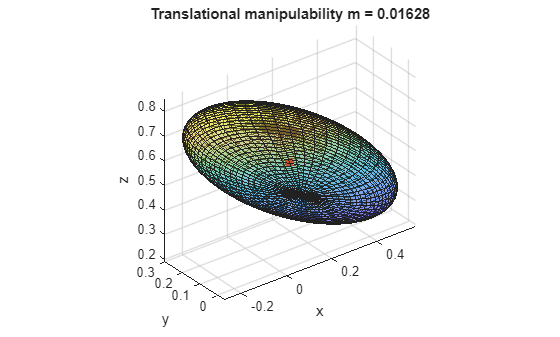


% % Unit sphere -> ellipsoid: E = U*S*[sphere points]
[xu,yu,zu] = sphere(50);
P_t = [xu(:)'; yu(:)'; zu(:)'];                           % 3×N
E_t = U_t*S_t*P_t;                                        % 3×N, base frame
x_t = reshape(E_t(1,:), size(xu))+p_ee(1);
y_t = reshape(E_t(2,:), size(yu))+p_ee(2);
z_t = reshape(E_t(3,:), size(zu))+p_ee(3);

figure; surf(x_t,y_t,z_t,'FaceAlpha',0.4'); hold on;

plot3(p_ee(1),p_ee(2),p_ee(3),'.','MarkerSize',20,'Color','r');
axis equal; grid on; xlabel x; ylabel y; zlabel z;
title(sprintf('Translational manipulability m = %.4g', m_t));

see in Rviz

JointStatesToRviz(config, 'ur3e', [],  'Ellipsoid', true);

### Robotic System Toolbox

using the Robotic System Toolbox, you can easily compute the manipulability index of a configuration. 

m_rs = manipulabilityIndex(ur3e, config');

this will return the combined manipulability of translation and rotation. 

for a set of task space dimension you can check the index as: 

m_rs_rot = manipulabilityIndex(ur3e, config',MotionComponent="angular");

or for for specific motions you can use a vector to specify the required taskspace. 

m_rs_custom = manipulabilityIndex(ur3e, config',MotionComponent=[1,0,1,1,0,0]);

the function generateRobotWorkspace, allow you to visualize the workspace of your robot and analyze the manipulability index in each point. 

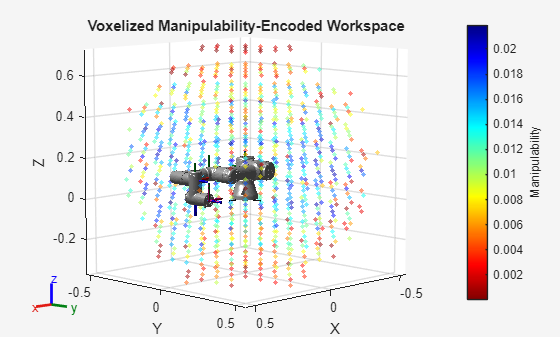

show(ur3e);
ee = "tool0";

rng default
[workspace,configs] = generateRobotWorkspace(ur3e,{},ee,IgnoreSelfCollision="on");

mIdx = manipulabilityIndex(ur3e,configs,ee);

hold on
showWorkspaceAnalysis(workspace,mIdx,Voxelize=true)
axis auto
title("Voxelized Manipulability-Encoded Workspace")
hold off

## Rank of the Jacobian 

The rank of the Jacobian provides crucial information about the robot's manipulability. For a given task-space dimension N, the rank of the corresponding part of the Jacobian should be N to achieve full manipulability. If the Jacobian's rank is less than N, there exists at least one motion that cannot be realized or independently controlled.

In linear algebra terms, the rank corresponds to the number of pivot elements in the row-echelon form of the Jacobian. Each pivot represents an independent direction of motion in task space. Missing pivots indicate dependent motions and a reduction in manipulability.

Similarly, in terms of singular values, each nonzero singular value corresponds to a controllable direction. A zero singular value indicates a direction along which the end-effector cannot move, directly reflecting the loss of manipulability in that direction.

N = rank(J)

N = 6

N_t = rank(J_t)

N_t = 3

N_r = rank(J_r)

N_r = 3

## Singularities

Points where the Jacobian looses rank are known as singularities or singular configurations. In these configurations the ellipsoid becomes an ellipse or a line (e.g. when considering the translation). 

There are three types of Singularities, 

wrist singularity

reachability singularity 

ellbow singularity. 

View the Ellipsoid in Rviz while crossing through a singularity

trajectory1 = quinticpolytraj([0,0,0,0,0,0; 0,-pi/2,0,-pi/2,0,0; -pi/2,-pi/3,pi/5,pi/7,-pi/10,pi;0,0,0,0,0,0]',[0,10, 20,30],linspace(0,30,300));
JointStatesToRviz(trajectory1, 'ur3e', 30, 'Ellipsoid', true, 'EllipsoidKind', 'trans')

ans = logical
   1


## Redundancy

A manipulator is said to be kinematically redundant when it has more degrees of freedom (DoFs) than the dimensionality of its task space. The task space typically corresponds to the number of independent variables required to fully specify the end-effector's position and orientation (e.g., 6 DoFs for a full 3D pose). For example, a 7-joint robotic arm operating in three-dimensional space has 7 DoFs, but the end-effector pose only requires 6, the extra DoF introduces redundancy. Redundancy allows the robot to achieve the same end-effector pose with multiple joint configurations, enabling optimization of secondary criteria such as obstacle avoidance, joint limit avoidance, energy efficiency, or preferred postures. Understanding and exploiting redundancy is fundamental in trajectory planning and inverse kinematics.